# Testar MEuler

## Exercício que consta no anexo de manuscritos da AM2_Matemática 

Aula04T1_Pós-laboral,

26/03/2021     Arménio Correia     armenioc@isec.pt

09/04/2021     Paulo Gouveia        a2020121705.isec.pt

09/04/2021     Miguel Ferreira       a2020107016.isec.pt

09/04/2021     Pablo Amaral         a2020143935.isec.pt

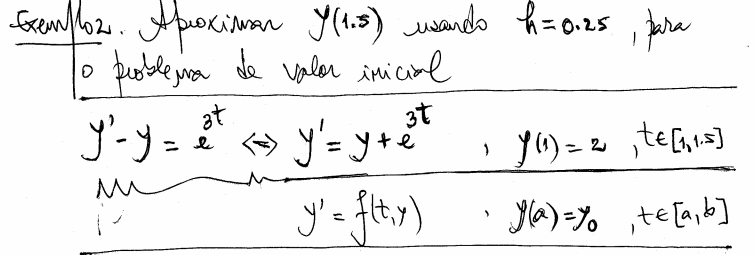

clear
%help function_hnadle

syms y(t)

f =@(t,y) y+exp(3*t)

f = function_handle with value:
    @(t,y)y+exp(3*t)


%f(0,1)
a = 1

a = 1

b = 1.5

b = 1.5000

n = 20

n = 20

y0 = 2

y0 = 2


yEuler = MEuler(f,a,b,n,y0)

yEuler =     2.0000    2.5521    3.1572    3.8195    4.5438    5.3353    6.1992    7.1417    8.1691    9.2883   10.5067   11.8324   13.2741   14.8410   16.5433   18.3918   20.3983   22.5754   24.9368   27.4971   30.2724




sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

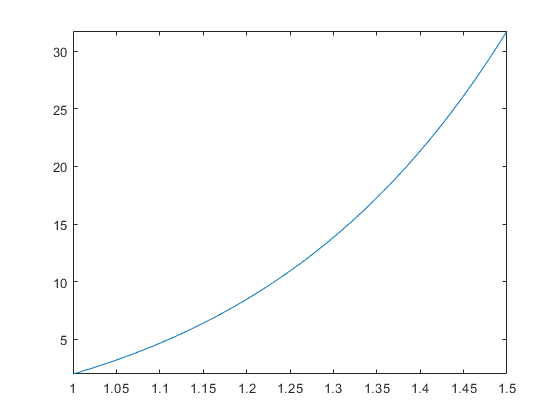

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)))

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))



h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroEuler = abs(yExata-yEuler);
tabela = [t.',yExata.',yEuler.',erroEuler.']

tabela =     1.0000    2.0000    2.0000    0.0000
    1.0250    2.5786    2.5521    0.0264
    1.0500    3.2129    3.1572    0.0557
    1.0750    3.9076    3.8195    0.0881
    1.1000    4.6677    4.5438    0.1238
    1.1250    5.4985    5.3353    0.1632
    1.1500    6.4058    6.1992    0.2066
    1.1750    7.3960    7.1417    0.2542
    1.2000    8.4757    8.1691    0.3065
    1.2250    9.6522    9.2883    0.3639


array2table(tabela,"VariableNames",{'t','Exata','Euler','erroEuler'})

ans = 21×4 table
      t      Exata     Euler     erroEuler 
    _____    ______    ______    __________

        1         2         2    1.7764e-15
    1.025    2.5786    2.5521       0.02643
     1.05    3.2129    3.1572      0.055713
    1.075    3.9076    3.8195      0.088094
      1.1    4.6677    4.5438       0.12384
    1.125    5.4985    5.3353       0.16323
     1.15    6.4058    6.1992       0.20658
    1.175     7.396    7.1417       0.25423
      1.2    8.4757    8.1691       0.30653
    1.225    9.6522    9.2883       0.36388
     1.25    10.933    10.507       0.42669
    1.275    12.328    11.832       0.49542
      1.3    13.845    13.274       0.57056
    1.325    15.494    14.841       0.65265
     1.35    17.285    16.543       0.74225
    1.375    19.232    18.392       0.83998


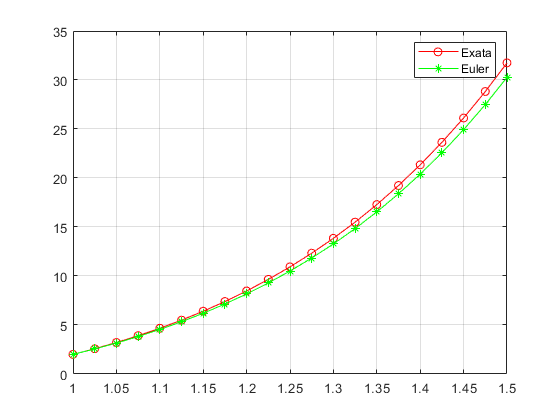


plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
hold off
grid on
legend('Exata','Euler')


%whos

 
